# BallisticTrajectory_Project2

This algorithm is designed to plot the trajectory of a cannon shell at various angles while neglecting and incorporating air resistance. The effects of air density are also considered in the 3rd figure. This is done using kinematic equations and the Euler method. 

## Declaration of Parameters

% variables for kinematics calculation
x0=0;                  % initial x posiition
y0=0;                  % initial y position
vi = 700;              % initial velocity
g = 9.81;              % acceleration due to gravity
ax = 0;                % acceleration in the x direction
t = 0:0.1:200;         % time elapsed

% variables for Euler approximation

iterations = 13800;       % iterations
dt = .009;                % step size
X = ones(1,iterations);   % X vector for theoretical solution
Y = ones(1,iterations);   % Y vector for theoretical solution
AirResist = 4*10.^-5;     % Drag coeffiecient divided by mass      
xk = [];        % define storing variable for exact x position to be a matrix
yk = [];        % define storing variable for exact y position to be a matrix
Xmaster = [];   % define storing variable for approximate X position w/o density correction to be a matrix
Ymaster = [];   % define storing variable for approximate Y position w/o density correction to be a matrix
Xpmaster = [];  % define storing variable for approximate X position w/ density correction to be a matrix
Ypmaster = [];  % define storing variable for approximate Y position w/ density correction to be a matrix

% density correction variables
a = 6.5*10.^-3;     %[K/m]
T_0 = 288.2;        % sea level temperature [K]
alpha = 2.5;        % exponent for air medium
rho_0 = 1.225;      % density at sea level [Kg/m^3]

## Trajectory Calculations

for angle = 30:5:55
    % kinematic
    x = x0+vi*cosd(angle)*t+(ax*t.^2)/2;     % x calculation
    y = y0+vi*sind(angle)*t-(g*t.^2)/2;      % y calculation   
    
    % initialize velocities
    Vx = 700*ones(1,1000)*cosd(angle); % x initial velocity
    Vy = 700*ones(1,1000)*sind(angle); % y initial velocity
    v = sqrt(Vx.^2+Vy.^2);             % initial velocity
    
    % Euler approximation
    for i = (1:1:iterations)
        X(i+1) = X(i)+ Vx(i).*dt;         % displacement
        Y(i+1) = Y(i)+ Vy(i).*dt;         % height
        v = sqrt(Vx(i).^2+Vy(i).^2);      % velocity changes due to drag
        Fdragx = (-AirResist).*v.*Vx(i);  % force of drag in the x direction
        Fdragy = (-AirResist).*v.*Vy(i);  % force of drag in the y direction
        Vx(i+1) = Vx(i)+(Fdragx)*dt;      % velocity in X direction
        Vy(i+1) = Vy(i) +(-g+Fdragy)*dt;  % velocity in Y direction
    end
    
    xk = [xk; x];           % Store exact x into matrix at various angles
    yk = [yk; y];           % Store exact y into matrix at various angles
    Xmaster = [Xmaster; X]; % Store approximate x into matrix at various angles
    Ymaster = [Ymaster; Y]; % Store approximate y into matrix at various angles
end

## Density Correction

for angle = 35:10:45
    
    Xp = ones(1,iterations);           % X vector for theoretical solution
    Yp = ones(1,iterations);           % Y vector for theoretical solution

    Vxp = 700*ones(1,1000)*cosd(angle); % x initial velocity
    Vyp = 700*ones(1,1000)*sind(angle); % y initial velocity
    vp = sqrt(Vx.^2+Vy.^2);             % initial velocity
    
    for i = (1:1:iterations)
        Xp(i+1) = Xp(i)+ Vxp(i).*dt;                       % displacement
        Yp(i+1) = Yp(i)+ Vyp(i).*dt;                       % height
        rho = rho_0.*(1-(a.*Yp(i))./T_0).^alpha;           % density calculation
        vp = sqrt(Vxp(i).^2+Vyp(i).^2);                    % velocity changes due to drag
        Fdragxp = (-AirResist*(rho/rho_0)).*vp.*Vxp(i);    % force of drag w/ density correction in the x direction
        Fdragyp = (-AirResist*(rho/rho_0)).*vp.*Vyp(i);    % force of drag w/ density correction in the y direction
        Vxp(i+1) = Vxp(i)+(Fdragxp)*dt;                    % velocity in X direction
        Vyp(i+1) = Vyp(i) +(-g+Fdragyp)*dt;                % velocity in Y direction      
    end
    
    Xpmaster = [Xpmaster; Xp];  % matrix of X position at different angle w/ density correction
    Ypmaster = [Ypmaster; Yp];  % matrix of Y position at different angle w/ density correction
end

## Plot with drag - Figure 2.4 (a)

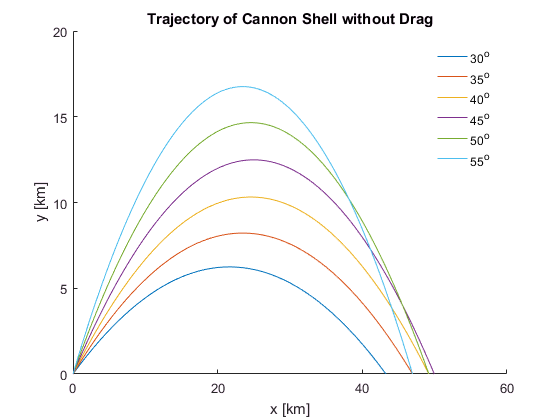

figure(1);
hold on;   % hold on to add different angles to plot

for i = 1:1:6
    plot(xk(i,:)./1000,yk(i,:)./1000);              % plot figure - convert to km
end
                 

title('Trajectory of Cannon Shell without Drag');   % create title
xlabel('x [km]');                                   % label x axis
ylabel('y [km]');                                   % label y axis

xticks([0 20 40 60]);                               % x axis increments
yticks([0 5 10 15 20]);                             % y axis increments

lgd2 = legend('30^{o}', '35^{o}', '40^{o}',... % create legend
        '45^{o}', '50^{o}', '55^{o}');
lgd2.EdgeColor = 'none';

ylim([0 20]);                                       % set y limits
xlim([0 60]);                                       % set x limits

hold off;

## Plot without drag - Figure 2.4 (b)

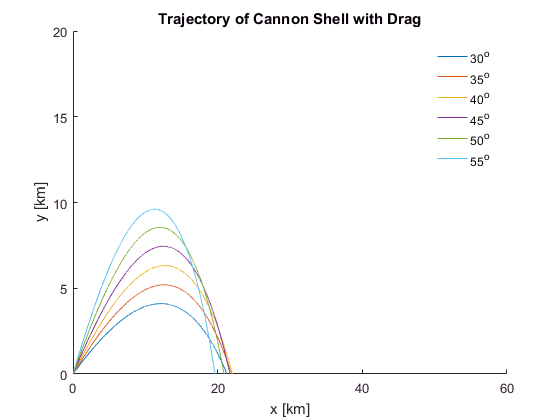

figure(2);
hold on;   % hold on to add different angles to plot

for i = 1:1:6
    plot(Xmaster(i,:)./1000,Ymaster(i,:)./1000);    % plot figure - convert to km
end

title('Trajectory of Cannon Shell with Drag');      % create title
xlabel('x [km]');                                   % label x axis
ylabel('y [km]');                                   % label y axis

xticks([0 20 40 60]);
yticks([0 5 10 15 20]);

lgd = legend('30^{o}', '35^{o}', '40^{o}',... % create legend
        '45^{o}', '50^{o}', '55^{o}');
lgd.EdgeColor = 'none';

ylim([0 20]);                                       % set y limits
xlim([0 60]);                                       % set x limits

hold off;

## Plot with drag - Figure 2.5

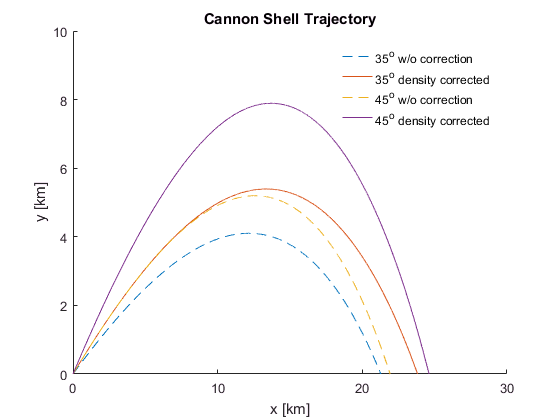

figure(3);
hold on;    % hold on to add different angles to plot

for i = 1:1:2
    plot(Xmaster(i,:)./1000,Ymaster(i,:)./1000, '--');     % plot figure without density correction
    plot(Xpmaster(i,:)./1000,Ypmaster(i,:)./1000);     % plot figure with density correction
end


lgd3 = legend('35^{o} w/o correction',...                     
        '35^{o} density corrected',...
        '45^{o} w/o correction',...
        '45^{o} density corrected');
lgd3.EdgeColor = 'none';

title('Cannon Shell Trajectory');    % create title
xlabel('x [km]');                    % label x axis
ylabel('y [km]');                    % label y axis

xticks([0 10 20 30]);                % x axis increments
yticks([0 2 4 6 8 10]);              % y axis increments

ylim([0 10]);                        % set y limits
xlim([0 30]);                        % set x limits